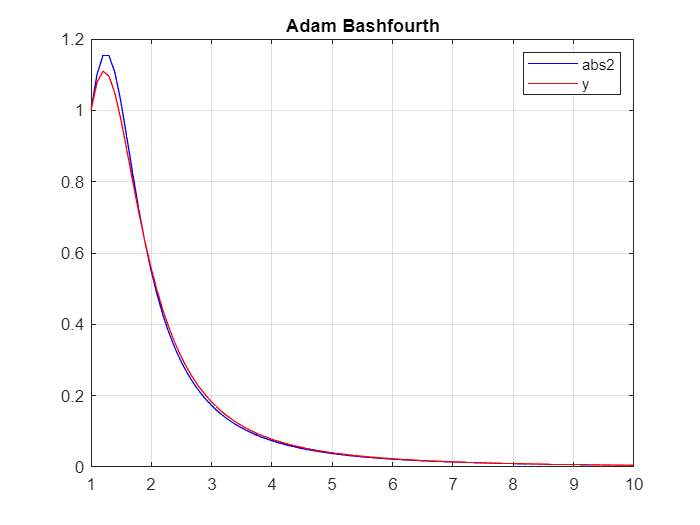


f = @(t,y)2 * (y/t) - t.^2*y.^2;
h = 0.1;
t(1) = 1;
y(1) = 1;
n = (10 - 1)/h;
for i = 1:n
t(i + 1) = t(i) + h;
y(i + 1) = y(i) + h*f(t(i),y(i));
y(i + 2) = y(i + 1) + (h/2)*(3*f(t(i + 1), y(i + 1)) - f(t(i), y(i)));
end
t = linspace(1,10,92);
true_y = (5*t.^2)./(t.^5 + 4);
plot (t, y, 'b')
hold on
plot(t,true_y, 'r');
grid on
title('Adam Bashfourth')
legend('abs2','y')